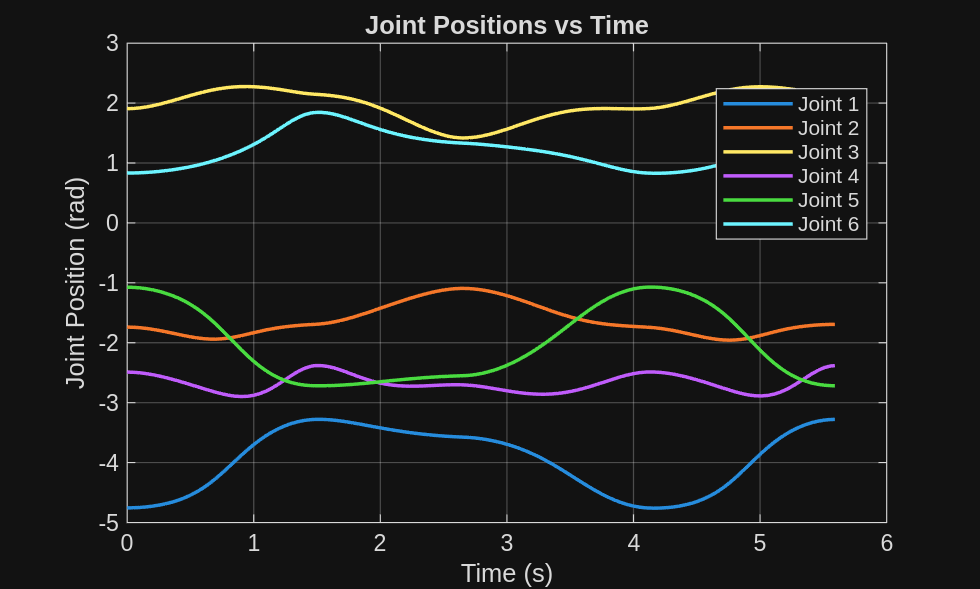

%% Read and plot ROS joint-space trajectory log
% Expects file: ros_js_trajectory_log.txt
% Log format per line:
% ... t=0.000 | Joint 1 [pos vel] | Joint 2 [pos vel] | ... | Joint 6 [pos vel]

clear; clc; close all;

filename = 'ros_js_trajectory_log.txt';
fid = fopen(filename, 'r');
if fid == -1
    error('Could not open file: %s', filename);
end

% Containers
t = [];
q = [];
qd = [];

line = fgetl(fid);
while ischar(line)
    if contains(line, 't=') && contains(line, 'Joint 1')
        % Extract time
        time_token = regexp(line, 't=([-\d\.]+)', 'tokens', 'once');
        
        % Extract all joint [position velocity] pairs
        joint_tokens = regexp(line, 'Joint\s+\d+\s+\[([-\d\.]+)\s+([-\d\.]+)\]', 'tokens');
        
        if ~isempty(time_token) && numel(joint_tokens) == 6
            t(end+1,1) = str2double(time_token{1});
            
            q_row = zeros(1,6);
            qd_row = zeros(1,6);
            for j = 1:6
                q_row(j)  = str2double(joint_tokens{j}{1});
                qd_row(j) = str2double(joint_tokens{j}{2});
            end
            
            q(end+1,:) = q_row;
            qd(end+1,:) = qd_row;
        end
    end
    line = fgetl(fid);
end

fclose(fid);

if isempty(t)
    error('No valid trajectory data found in %s', filename);
end

%% Plot joint positions
figure;
plot(t, q, 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Joint Position (rad)');
title('Joint Positions vs Time');
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6', ...
    'Location','best');

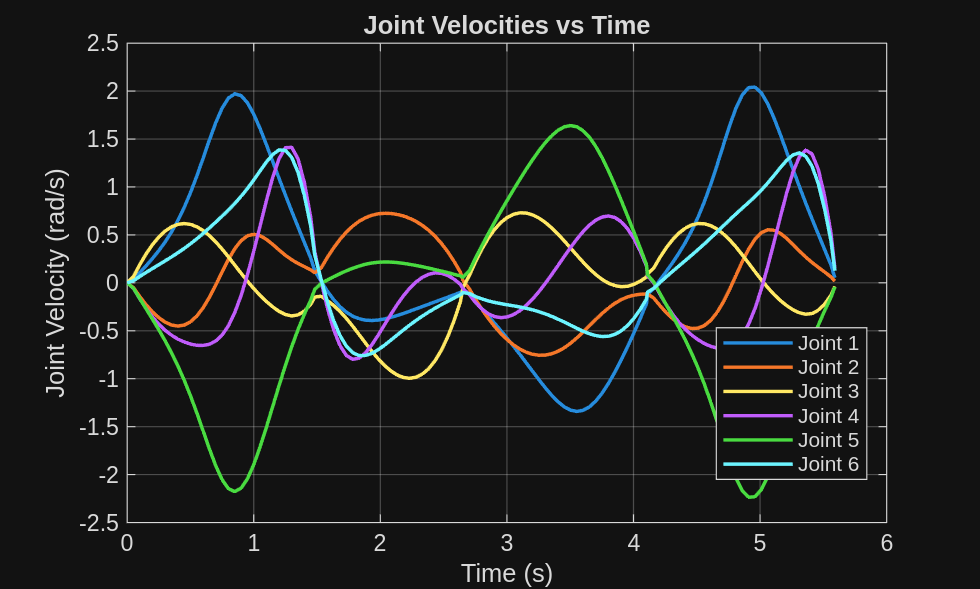


%% Plot joint velocities
figure;
plot(t, qd, 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Joint Velocity (rad/s)');
title('Joint Velocities vs Time');
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6', ...
    'Location','best');